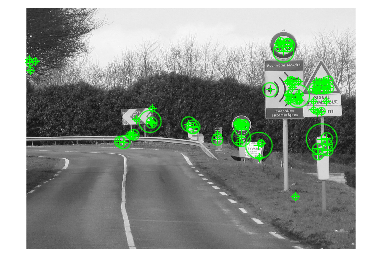

clf
% clear all
% 
% elaine = imread("elaine.jpg");
% elaine = im2double(elaine);
% 
% boat = imread("boat.png");
% boat = im2double(boat);
% 
% f_boat=fftshift(fft2(boat));
% 
% figure(1)
% imshow(log(abs(f_boat))/max(max(log(abs(f_boat)))))
% 
% f_elaine=fftshift(fft2(elaine));
% figure(2)
% imshow(log(abs(f_elaine))/max(max(log(abs(f_elaine)))))
% 
% figure(3)
% imshow(angle(f_elaine))
% figure(4)
% imshow(angle(f_boat))
% 
% figure(5)
% imshow(ifft2(fftshift(f_elaine)))
% 
% figure(6)
% imshow(ifft2(fftshift(f_boat)))
% 
% %% filtre aucun rapport mdr
% f_elaine = fft2(elaine);
% f_boat = fft2(boat);
% 
% fftphelaine = abs(f_elaine).*exp(1i*angle(f_boat));
% fftphboat = abs(f_boat).*exp(1i*angle(f_elaine));
% 
% phelaine = ifft2(fftphelaine);
% phboat = ifft2(fftphboat);
% 
% figure(7)
% imshow(phelaine)
% 
% figure(8)
% imshow(phboat)
% 
% %% sous-echantillonnage et filtre
% 
% 
% boat_e=boat(1:2:end,1:2:end);
% elaine_e=elaine(1:2:end,1:2:end);
% 
% filtre = [1;2;1]*[1 2 1]/16;
% 
% boat_filtre =conv2(boat,filtre);
% boat_filtre=boat_filtre(1:2:end,1:2:end);
% elaine_filtre =conv2(elaine,filtre);
% elaine_filtre=elaine_filtre(1:2:end,1:2:end);
% 
% figure(9)
% imshow(boat_e)
% figure(10)
% imshow(boat_filtre)
% 
% figure(11)
% imshow(elaine_e)
% figure(12)
% imshow(elaine_filtre)
% 
% %% binarisation couleur
% 
% figure(13)
% boat = imread("boat.png");
% imhist(boat)
% 
% seuil = 100;
% Ib =ones(size(boat));
% Ib(boat>seuil)=0;
% 
% figure(14)
% imshow(Ib)
% 
% %detection  du seuil auto
% level = graythresh(boat);
% 
% Ib = zeros(size(boat));
% Ib(boat>level*255)=1;
% 
% figure(15)
% imshow(Ib)

% %% rgb
% 
% pions = im2double(imread("pions.jpg"));
% pionshsv = rgb2hsv(pions);
% hue = pionshsv(:,:,1);
% 
% figure(16)
% imhist(hue)
% 
% maskJ = zeros(size(hue));
% maskJ(hue>0.95 & hue<1 | hue>0.1 & hue<0.2) = 1;
% 
% pionsJaunes = pions;
% 
% for i = 1:3
%     pionsJaunes(:,:,i) = squeeze(pionsJaunes(:,:,i)).*maskJ;
% end
% 
% figure(17)
% imshow(pionsJaunes)
% 
% %% Erosion-dilatation
% 
% 
% st = strel("square",8);
% pionsJaunesErrode = imerode(pionsJaunes,st);
% 
% figure(18)
% imshow(pionsJaunesErrode)
% st = strel("disk",1);
% pionsJaunesDilat = imdilate(pionsJaunesErrode,st);
% 
% figure(19)
% imshow(pionsJaunesDilat)
% 
% %% contour
% 
% pionsJaunesCont = pionsJaunesDilat - pionsJaunesErrode;
% figure(20)
% imshow(pionsJaunesCont)
% 
% 
% %% contour gradiant
% 
% 
% 
% pionsJaunesErrode = rgb2gray(pionsJaunesErrode) ;
% pionsJaunesContSobel = edge(pionsJaunesErrode, "sobel");
% figure(21)
% imshow(pionsJaunesContSobel)
% 
% 
% pionsJaunesContPrewitt  = edge(pionsJaunesErrode, "prewitt");
% figure(22)
% imshow(pionsJaunesContPrewitt)
% 
% 
% pionsJaunesContCanny = edge(pionsJaunesErrode, "canny",[0.05 0.1]);
% 
% figure(23)
% imshow(pionsJaunesContCanny)
% 
% pionsJaunesContRobert  = edge(pionsJaunesErrode, "roberts");
% figure(24)
% imshow(pionsJaunesContRobert)
% 
% %% Reconnaissance d'image
% 
% [centerCircle,rayons] = imfindcircles(pionsJaunesContCanny,[50 150], 'Sensitivity', 0.95);
% 
% centerCircle11 = centerCircle(1:size(centerCircle,1),:); 
% rayons11 = rayons(1:size(centerCircle,1));
% 
% 
% figure(25)
% imshow(pionsJaunesContCanny)
% hold on
% viscircles(centerCircle11, rayons11,'EdgeColor','b');
% 
% 
% %% Template matching 
% 
% alphabet = im2double(imread("Alphabet.jpg"));
% lettreU = im2double(imread("lettreU.jpg"));
% 
% alphabet = rgb2gray(alphabet) ;
% 
% figure(26)
% montage({alphabet,lettreU})
% 
% c = normxcorr2(lettreU,alphabet);
% figure(27)
% surf(c)
% shading flat
% [ypeak,xpeak] = find(c==max(c(:)));
% yoffSet = ypeak-size(lettreU,1);
% xoffSet = xpeak-size(lettreU,2);
% figure(28)
% imshow(alphabet)
% drawrectangle(gca,'Position',[xoffSet,yoffSet,size(lettreU,2),size(lettreU,1)],'FaceAlpha',0);

%% extraction de caracteristique

stan = im2double(imread("route50.jpg"));
stan = rgb2gray(stan) ;
stan2 = im2double(imread("ref50.jpg"));
stan2 = rgb2gray(stan2) ;

%detectHarrisFeatures ne prend pas en compte la perspective
points = detectSURFFeatures(stan);
figure(29)
imshow(stan); 
hold on;
plot(points.selectStrongest(90));

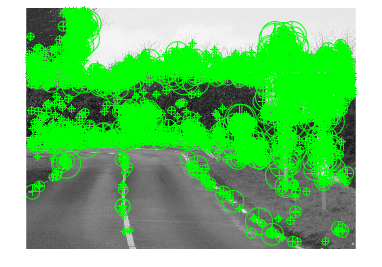


[features, valid_points] = extractFeatures(stan,points,'Upright',true);
figure(30)
imshow(stan); 
hold on;
plot(valid_points,'showOrientation',true);

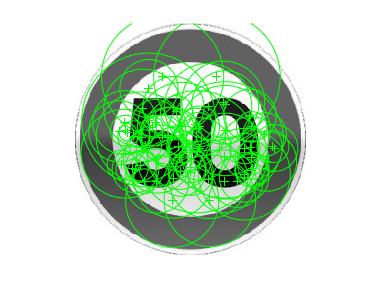



points2 = detectSURFFeatures(stan2);
figure(31)
imshow(stan2); 
hold on;
plot(points2.selectStrongest(90));

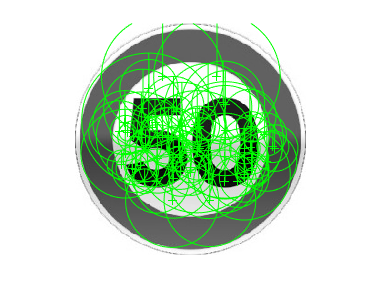


[features2, valid_points2] = extractFeatures(stan2,points2,'Upright',true);
figure(32)
imshow(stan2); 
hold on;
plot(valid_points2,'showOrientation',true);

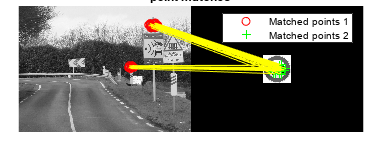



indexPairs = matchFeatures(features,features2,"MaxRatio",0.9);

matchedPoints1 = valid_points(indexPairs(:,1),:);
matchedPoints2 = valid_points2(indexPairs(:,2),:);

figure(33); 
ax = axes;
showMatchedFeatures(stan,stan2,matchedPoints1,matchedPoints2,'montage');
title(ax, 'point matches');
legend(ax,'Matched points 1','Matched points 2');